## **Question 1**


$$\begin{array}{l}
\min /\max Z=\left(\textrm{x1}-3\right)2+\left(\textrm{x2}-2\right)2\left(1\right)\\
s\ldotp t\ldotp \\
\textrm{x21}+\textrm{x2}\le 5\\
\textrm{x1}+2\textrm{x2}\le 4\\
\textrm{x1},\textrm{x2}\ge 0
\end{array}$$
				

Sketch the feasible region and the contours of the objective function. Identify the optimum graphically. 

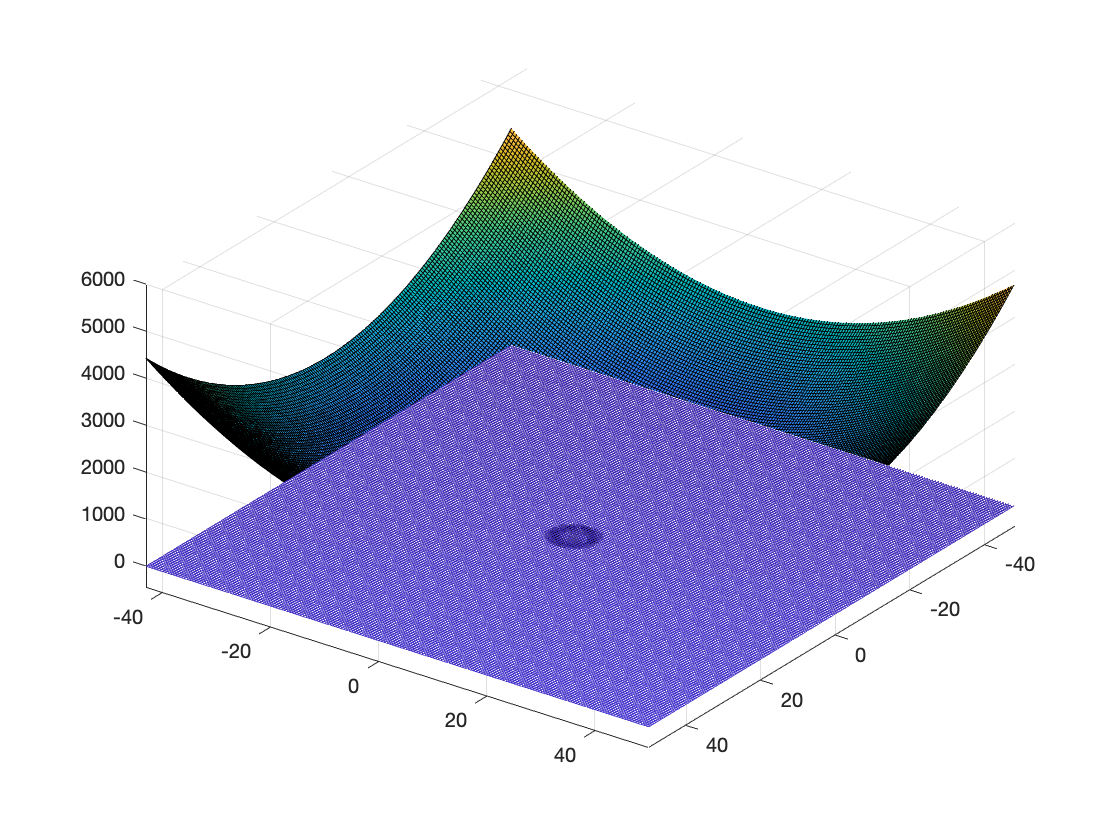


[x,y] = meshgrid(-50:0.5:50,-50:0.5:50);

title('Question 1')
xlabel('x1')
ylabel('x2')


MyFunc = power((x-3),2) + power((y-2),2);

const1 = x^2 + y^2 - 5;
const2 = x + 2*y - 4;


surf(x,y,MyFunc)

hold on
surf(x,y,MyFunc)

mesh(x,y,const1,const2)


hold off 

xlim([-43.0 50.0])
ylim([-47.9 50.0])
zlim([-456 6000])
view([-36 -42])

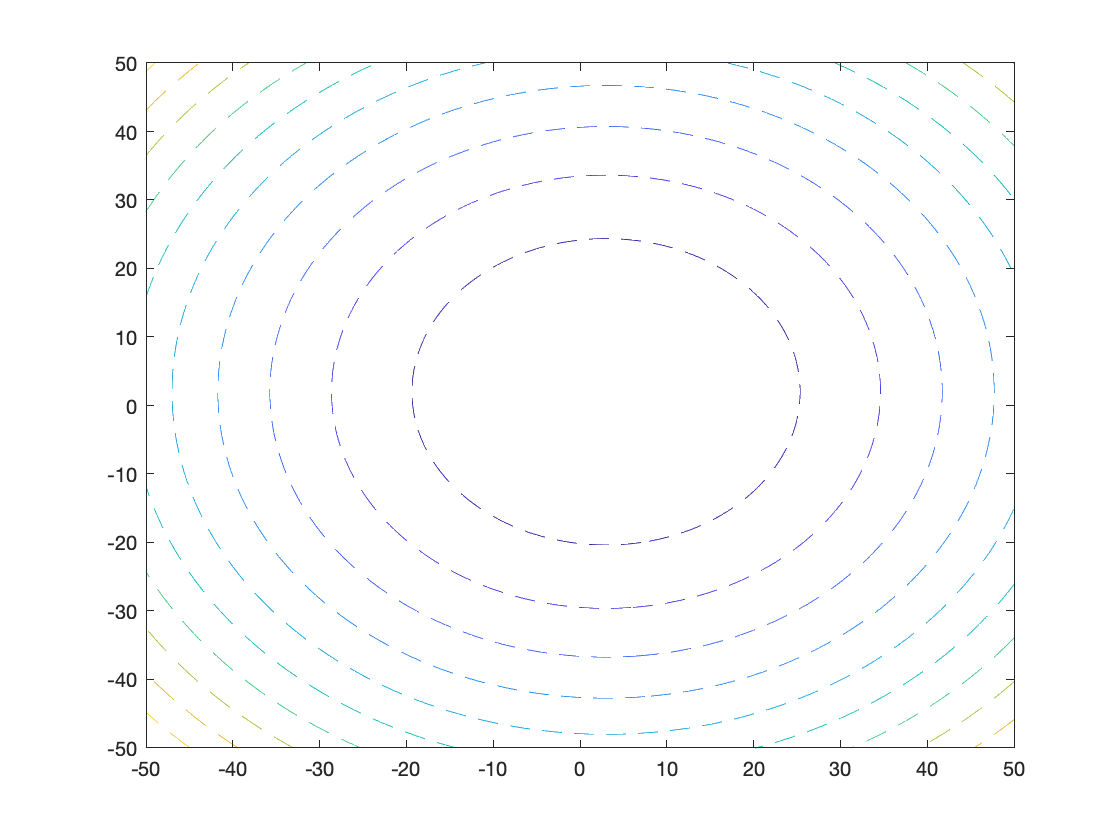


contour(x,y,MyFunc,'--')

## **Question 4**


$$\begin{array}{l}
\mathrm{Letf}\left(x\right)=\mathrm{max}\left\lbrace \mathrm{f1}\left(x\right),\mathrm{f2}\left(x\right)\right\rbrace \;\mathrm{where}\;\mathrm{f1}\left(x\right)=\left|x\right|-4,x\in R\;\mathrm{and}\;\mathrm{f2}\left(x\right)=\left(x-2\right)2-4,x\in R\ldotp \\
\mathrm{Draw}\;\mathrm{the}\;\mathrm{graph}\;\mathrm{of}\;f\left(x\right)\;\mathrm{and}\;\mathrm{discuss}\;\mathrm{its}\;\mathrm{convexity}\ldotp 
\end{array}$$


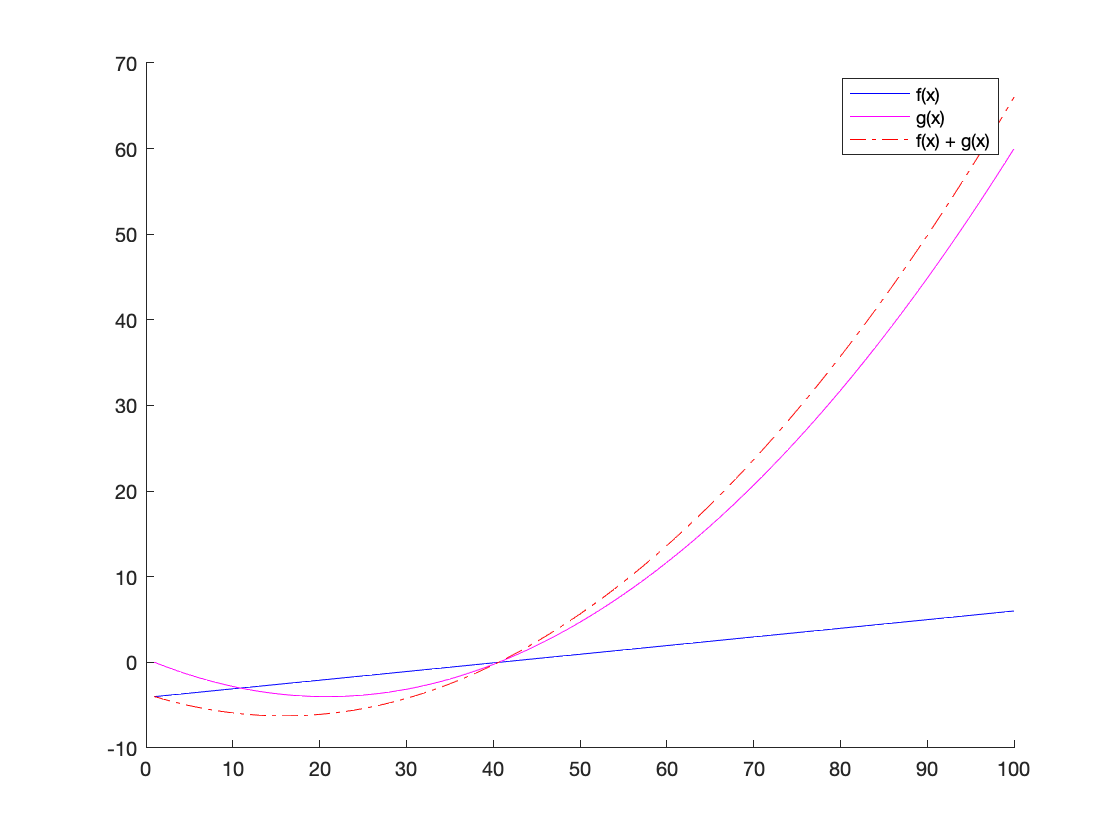

close all

x = linspace(0,10,100);

MyFunc1 = abs(x) - 4;
MyFunc2 = power((x-2),2) - 4;

hold on 

plot(MyFunc1, 'b')
plot(MyFunc2, 'm')
plot(MyFunc1 + MyFunc2, '-.r')

hold off

legend('f(x)','g(x)', 'f(x) + g(x)')